%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Davide Cunial 20 Ottobre 2016
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Extraction

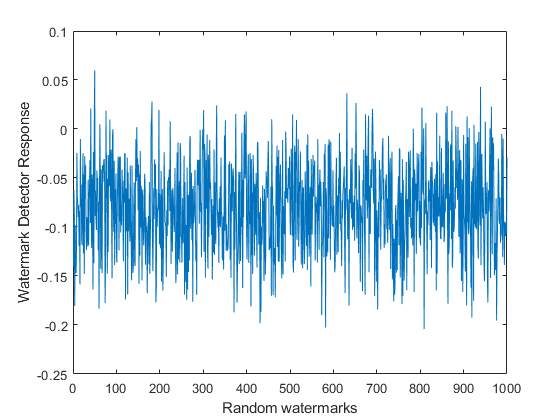

extracted_w = zeros(1,1024);
original_w=zeros(1,1024);
Iatt=I_inv;
%Iatt = imsharpen(Iatt, 'Radius', 1, 'Amount', 3);
n = size(Iatt);
Iatt = double(Iatt);
Iatt = imresize(Iatt, 0.6);
Iatt = imresize(Iatt, 1/0.6);
Iatt = uint8(Iatt(1:n(1), 1:n(2)));
rng(7); % Seed random generator
%Iatt = imnoise(Iatt,'gaussian',0,1);
%Iatt = imnoise(Iatt,'gaussian',0,0.009);
%Iatt = imgaussfilt(Iatt,0.8);
imwrite(uint8(Iatt), 'SSatt.jpg', 'Quality', 13);
Iatt = imread('SSatt.jpg');
delete('SSatt.jpg');



Iatt_re = dct2(Iatt);
Iatt_re = abs(reshape(Iatt_re,1,dimx*dimy));
k = 1000;
for j = 1:1024
    m = Ix(k);
    extracted_w(j) = (Iatt_re(m)/It_mod(m) - 1)/alpha;
    original_w(j) = (Itw_mod(m)/It_mod(m) - 1)/alpha;
%    Itw_mod(m) = It_mod(m)*(1+alpha*w(j));
   % k =round(k+(div/k));
   k=k+1;
   if(j==1)
        k=50000;
    end
end

rng(7);
w_new=zeros(1000,1024);
for n = 1:49
    w_new(n,:) = round(rand(1,1024));
end
w_new(50,:) = original_w;
for n =51:1000
    w_new(n,:) = round(rand(1,1024));
end

sim=zeros(1,1000);
for n = 1:1000
    sim(n) = extracted_w.*w_new(n,:)/sqrt(extracted_w.*extracted_w);
end

x = 1:1000;
plot(x,sim); xlabel('Random watermarks'); ylabel('Watermark Detector Response');

WPSNR(uint8(I_inv),uint8(Iatt))

WPSNR = +42.05 dB


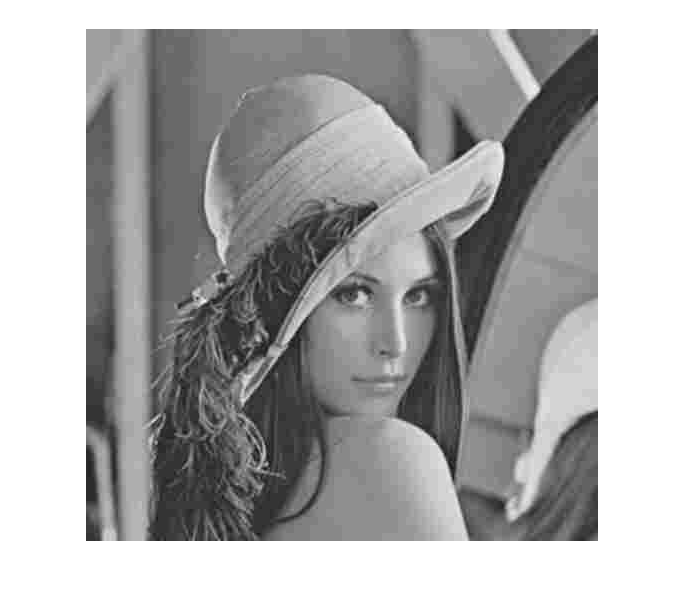


sorted=sort(sim,'descend');
figure(); imshow(Iatt);

ss=sorted(2)*(1.1);
if(sorted(2)<0)
     ss=sorted(2)*(0.9);
end
if(sim(50)>ss)
    	fprintf('true\n');
else
    fprintf('false\n');
end

true
